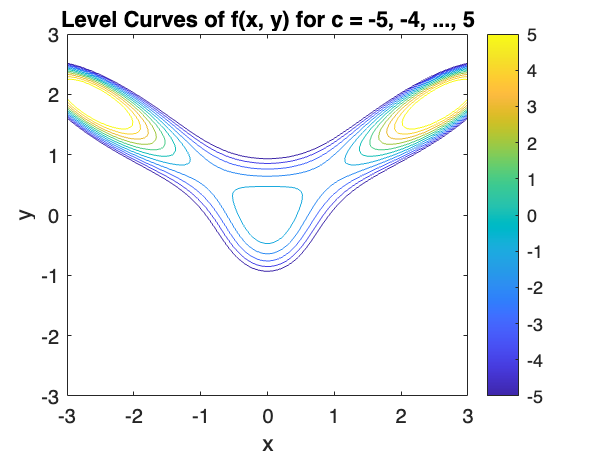

% Define the function
f = @(x, y) 10*x.^2.*y - 5*x.^2 - 4*y.^2 - x.^4 - 2*y.^4;

% Define the range for x and y
x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

% Create a grid of points
[X, Y] = meshgrid(x, y);

% Plot level curves for c = -5, -4, ..., 5
figure;
contour(X, Y, f(X, Y), -5:1:5);
xlabel('x');
ylabel('y');
title('Level Curves of f(x, y) for c = -5, -4, ..., 5');
colorbar;

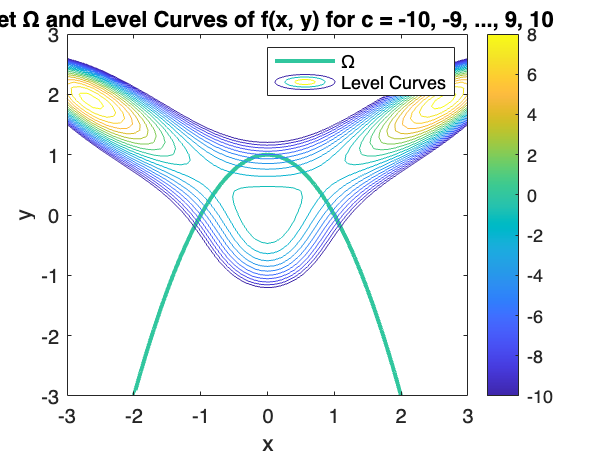


% Define the constraint set Ω
[x_omega, y_omega] = meshgrid(-3:0.1:3, -3:0.1:3);
constraint_set = -x_omega.^2 + 1 - y_omega;

% Plot the set Ω
figure;
contour(x_omega, y_omega, constraint_set, [0, 0], 'LineWidth', 2);
hold on;
% Plot level curves for c = -10, -9, ..., 9, 10
contour(x_omega, y_omega, f(x_omega, y_omega), -10:1:10);
xlabel('x');
ylabel('y');
title('Set Ω and Level Curves of f(x, y) for c = -10, -9, ..., 9, 10');
colorbar;
legend('Ω', 'Level Curves');


% Find stationary points
syms x y
grad_f = [diff(f(x, y), x); diff(f(x, y), y)];
stationary_points = solve(grad_f == [0; 0], [x, y]);

% Plot surface and stationary points
figure;
surf(X, Y, f(X, Y));
hold on;
% Plot stationary points
scatter3(stationary_points.x, stationary_points.y, f(stationary_points.x, stationary_points.y), 20, 'r', 'filled'); % Extrema points

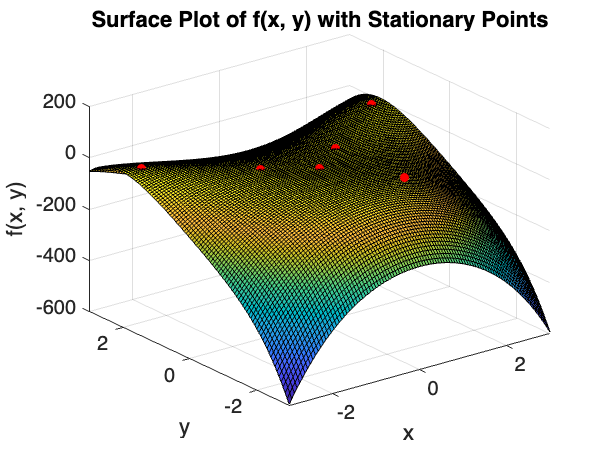

    x: [9×1 sym]
    y: [9×1 sym]



   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i
  -0.8567 + 0.0000i   0.6468 + 0.0000i
   0.8567 + 0.0000i   0.6468 + 0.0000i
  -2.6442 + 0.0000i   1.8984 + 0.0000i
   2.6442 + 0.0000i   1.8984 + 0.0000i
   0.0000 - 3.9020i  -2.5452 + 0.0000i
   0.0000 + 3.9020i  -2.5452 + 0.0000i



xlabel('x');
ylabel('y');
zlabel('f(x, y)');
title('Surface Plot of f(x, y) with Stationary Points');